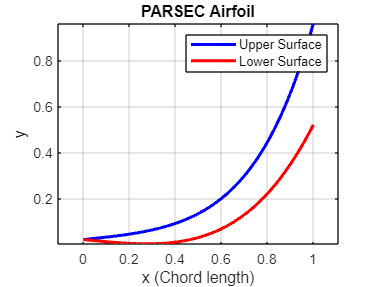

% PARSEC Airfoil Generation in MATLAB

% Define PARSEC parameters
r_LE = 0.02;        % Leading edge radius
y_TE = 0.0;         % Trailing edge offset
theta_TE = -2.0;    % Trailing edge slope (degrees)
k_uLE = 0.1;        % Upper surface curvature at leading edge
k_lLE = -0.1;       % Lower surface curvature at leading edge
k_uTE = 0.001;      % Upper surface curvature at trailing edge
k_lTE = -0.001;     % Lower surface curvature at trailing edge
x_camber = 0.4;     % Position of maximum camber
y_camber = 0.02;    % Value of maximum camber
x_thickness = 0.3;  % Position of maximum thickness
t_max = 0.12;       % Maximum thickness

% Define chord length
chord = 1.0;

% Create polynomial coefficients for upper and lower surfaces
% The polynomials are typically 6th order: y = a0 + a1*x + ... + a6*x^6
% Boundary conditions are used to determine the coefficients.

% Example polynomials (based on boundary conditions)
syms x

% Upper surface polynomial (example coefficients)
a_u = [r_LE, k_uLE, k_uTE, x_camber, y_camber, x_thickness, t_max];
y_u = a_u(1) + a_u(2)*x + a_u(3)*x^2 + a_u(4)*x^3 + a_u(5)*x^4 + a_u(6)*x^5 + a_u(7)*x^6;

% Lower surface polynomial (example coefficients)
a_l = [r_LE, k_lLE, k_lTE, x_camber, y_camber, x_thickness, -t_max];
y_l = a_l(1) + a_l(2)*x + a_l(3)*x^2 + a_l(4)*x^3 + a_l(5)*x^4 + a_l(6)*x^5 + a_l(7)*x^6;

% Generate airfoil coordinates
x_vals = linspace(0, chord, 100);
y_u_vals = double(subs(y_u, x_vals));
y_l_vals = double(subs(y_l, x_vals));

% Plot the airfoil
figure;
plot(x_vals, y_u_vals, 'b', 'LineWidth', 2); % Upper surface
hold on;
plot(x_vals, y_l_vals, 'r', 'LineWidth', 2); % Lower surface
axis equal;
xlabel('x (Chord length)');
ylabel('y');
title('PARSEC Airfoil');
legend('Upper Surface', 'Lower Surface');
grid on;

% https://en.wikipedia.org/wiki/NACA_airfoil

syms x

thickness = 0.5

thickness = 0.5000


m = 0.02

m = 0.0200

p = 0.4

p = 0.4000


yt = 5 * thickness * (0.2969 * sqrt(x) - 0.1260 * x - 0.3516 * x^2 + 0.2843 * x^3 - 0.1036 * x^4)

$$yt = \frac{2969\,\sqrt{x}}{4000}-\frac{879\,x^{2}}{1000}-\frac{63\,x}{200}+\frac{2843\,x^{3}}{4000}-\frac{259\,x^{4}}{1000}$$

yc = m / p^2 * (2 * p * x - x^2) * heaviside(p - x) + m / (1 - p)^2 * ((1 - 2*p) + 2*p*x - x^2) * heaviside(x - p)

$$yc = \mathrm{heaviside}\left(x-\frac{2}{5}\right)\,\left(-\frac{x^{2}}{18}+\frac{2\,x}{45}+\frac{1}{90}\right)+\mathrm{heaviside}\left(\frac{2}{5}-x\right)\,\left(\frac{x}{10}-\frac{x^{2}}{8}\right)$$

yu = yt + yc

$$yu = \mathrm{heaviside}\left(x-\frac{2}{5}\right)\,\left(-\frac{x^{2}}{18}+\frac{2\,x}{45}+\frac{1}{90}\right)-\frac{63\,x}{200}+\mathrm{heaviside}\left(\frac{2}{5}-x\right)\,\left(\frac{x}{10}-\frac{x^{2}}{8}\right)-\frac{879\,x^{2}}{1000}+\frac{2969\,\sqrt{x}}{4000}+\frac{2843\,x^{3}}{4000}-\frac{259\,x^{4}}{1000}$$

yl = yc - yt

$$yl = \frac{63\,x}{200}+\mathrm{heaviside}\left(x-\frac{2}{5}\right)\,\left(-\frac{x^{2}}{18}+\frac{2\,x}{45}+\frac{1}{90}\right)+\mathrm{heaviside}\left(\frac{2}{5}-x\right)\,\left(\frac{x}{10}-\frac{x^{2}}{8}\right)+\frac{879\,x^{2}}{1000}-\frac{2969\,\sqrt{x}}{4000}-\frac{2843\,x^{3}}{4000}+\frac{259\,x^{4}}{1000}$$

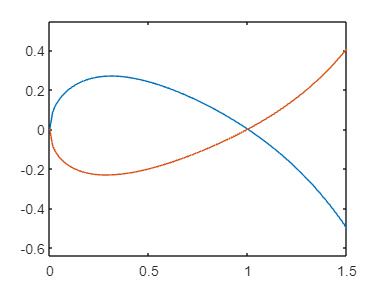

x_vals = linspace(0, 1);

figure;
axis equal;
plot(x_vals, double(subs(yu, x_vals)))
axis equal;
hold on;
plot(x_vals, double(subs(yl, x_vals)))
xlim([0 1]);
hold off;